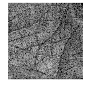

masterImage = imread("imageGeneratedFrom3D_dbRidotto40\2b33f905_005\immagine_1_0.0924.jpg");
imshow(masterImage);title("Immagine Master")

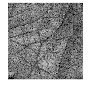

slave = imread("imageGeneratedFrom3D_dbRidotto40\2b33f905_003\immagine_1_0.0924.jpg");
imshow(slave);title("Immagine Slave")

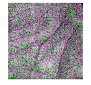

imshowpair(masterImage,slave,"Scaling","joint");

% All'interno di questa funzione, 
% vengono impostate varie opzioni, 
% tra cui il tipo di ottimizzazione, 
% le metriche di similarità e altri parametri che 
% influenzano come l'immagine viene registrata. 
% Le metriche di similarità misurano quanto bene 
% due immagini coincidono durante il processo di
% registrazione. Monomodal significa che le immagini
% sono acquisite con lo stesso sensore

[optimizer,metric] = imregconfig("monomodal");


% Questa funzione cerca di trovare una trasformazione che 
% allineerà l'immagine "slave" rispetto all'immagine 
% "masterImage"
tform = imregtform(slave,masterImage,"rigid",optimizer,metric);

% Una volta ottenuta la trasformazione, viene utilizzata la funzione 
% imwarp per applicarla all'immagine "slave". 
% Questo significa che ogni pixel nell'immagine "slave"
% viene trasformato e posizionato in base alla trasformazione calcolata.
movingRegistered = imwarp(slave,tform,"OutputView",imref2d(size(masterImage)));

% Converti l'immagine master in double se non lo è già
master = im2double(masterImage);
moving = im2double(movingRegistered);

% Calcola l'Errore Quadratico Medio (MSE)
mse = immse(moving, master);

% Calcola l'Errore Quadratico Medio Normalizzato (NMSE)
nmse = mse / mean(master(:).^2);

fprintf("Errore Quadratico Medio (MSE) per l'immagine %d: %.4f\n", mse);

Errore Quadratico Medio (MSE) per l'immagine 2.930697e-02: 

fprintf("Errore Quadratico Medio Normalizzato (NMSE) per l'immagine %d: %.4f\n", nmse);

Errore Quadratico Medio Normalizzato (NMSE) per l'immagine 1.467667e-01: 

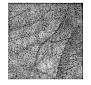

imshowpair(masterImage,movingRegistered,"blend","Scaling","joint");

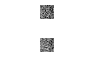

figure;subplot(2,1,1);imshow(masterImage);
subplot(2,1,2);imshow(movingRegistered);

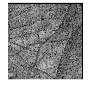

figure;imshow(movingRegistered);title("Immagine Slave con Correzione")

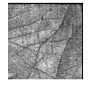

rect = [10 15 40 40]; 
[filteredImage] = SRAD(movingRegistered,40,0.9,rect);
figure;imshow(filteredImage); title("SRAD")

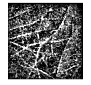


%BOTTOM HAT FILTER 4 DIREZIONI
bottomHatFiltered = bottomhat4way(filteredImage);
imshow(bottomHatFiltered); title('bottomHat'); figure;

%imwrite(bottomHatFiltered, strcat(filename,'_BotHat.jpg'));
 

%AUMENTO CONTRASTO
contrastAdjusted = imadjust(bottomHatFiltered,stretchlim(bottomHatFiltered),[]);
imshow(contrastAdjusted); title('ContrastAdjusted'); figure;

%imwrite(contrastAdjusted,strcat(filename,'_contrastAdj.jpg'));


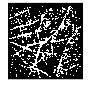



%BINARIZZAZIONE
A = contrastAdjusted;
meanValue=mean2(A);
threshold = meanValue*1.6;   % più è alto il fattore di scala meno dettagli saranno presenti
A_bw = A > threshold;
imshow(A_bw); title('binarizzazione'); figure;

%imwrite(A_bw, strcat(filename,'_Bin.jpg'));


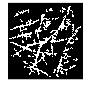


%CLEANING
CC= bwconncomp(A_bw);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);  
BW2 = ismember(L, find([S.Area] >= 500));
imshow(BW2); title('cleaning'); figure;

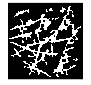


%imwrite(BW2, strcat(filename,'_cleaning.jpg'));

%CLOSING
se=strel('disk', 10);
closing=imclose(BW2, se);
imshow(closing); title('closing'); figure;

%imwrite(closing, strcat(filename,'_closing.jpg'));



% %imwrite(filling, strcat(filename,'_filling.jpg'));
% filling= imfill(closing,'holes');
% imshow(filling); title('filling'); figure;

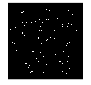


%THINNING
thinning= bwmorph(closing, 'thin', inf);
imshow(thinning);title('thinning');figure;

%imwrite(thinning, strcat(filename,'thinning.jpg'));

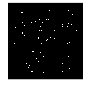


%PRUNNING
prun= bwmorph( thinning, 'spur', 21);
imshow(prun);title('prunning');figure;

%imwrite(prun, strcat(filename,'_prunning.jpg'));

%CLEANING LINEE PICCOLE
BWz = bwareaopen(prun, 30);
imshow(BWz);title('linee piccole');figure;

%imwrite(BWz, strcat(filename,'_lineePicc.jpg'));

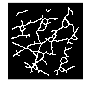


%DILATAZIONE WARING RIMETTERE COME PRIMA DISK 6
dilatation_mask= strel('disk', 6);
dilatedImageDat= imdilate(BWz, dilatation_mask);
imshow(dilatedImageDat); title('dilatazione'); figure;

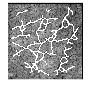


%dlmwrite(strcat(filename,'.dat'),dilatedImageDat);
%imwrite(dilatedImageDat,strcat(fullpathName,'_dilatazione.jpg'))

rgbImage = cat(3, movingRegistered, movingRegistered, movingRegistered);
%SOVRAPPOSIZIONE %%WARNING:RIMETTERE COME PRIMA
[m n1]= size(A);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImageDat(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=255;
        rgbImage(i,j,3)=255;
        end 
    end 
 end	 

imshow(rgbImage);title('Template 2D Post Correzione Geometrica'); figure;